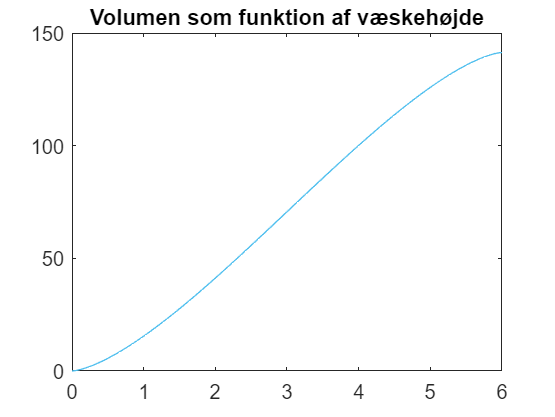

cylindvol(3,5, 'Volumen som funktion af væskehøjde')

function cylindvol = cylindvol(r, L, plottitle)
    
    Vol = @(h) (r.^2.*acos((r-h)./r) - (r-h).*sqrt(2.*r*h - h.^2))*L;

    hlin = linspace(0, 2*r);
    
    plot(hlin, Vol(hlin))

    title(string(plottitle))
end